# VD Workbench

% clear; clf; % Remember to clear after importing a different file / making major changes!

% MODES
GTYPE = "C185";      % Switches the accelerometer used for calculations
SPEEDMODE = "GPS";  % Switches the speed data used for calculations
DATATYPE = "PreTrim";   % Changes the lap finding and run trimming behavior 

% IMPORT
addpath("./Functions/");
if exist("run", "var") ~= 1
    [filename, path] = uigetfile('*.csv', 'Select First MoTeC Output File');
    run = motecImport(filename, path);
end

% TRIM
if DATATYPE == "LapsBeacon"
    li = find(run.LapNumber > min(run.LapNumber) & run.LapNumber < max(run.LapNumber));
    run = run(li,:); % trim the original run variable
end

% HELPER VARIABLES 
[gLat, gLong, speed, time] = SetupVariables(run, GTYPE, SPEEDMODE);
gLat = smoothdata(gLat,'gaussian',100);
car = FB2223();
lapZero = min(run.LapNumber) - 1; 
lapMax = max(run.LapNumber); 


## Calc Code

% Calculations over the whole file
[UA, AA, WA] = UndersteerAngle(gLat,speed,run.SteeredAngle,car);
[TA, gMaxes, gThrottles] = ThrottleAcceptance(run, gLat); 

% Calculations per lap
for i = 1:lapMax-lapZero
    [i1, i2] = LapBounds(run, lapZero, lapMax, i);
    
    Lap(i) = i;
    lapTimes(i) = time(i2) - time(i1);
    
    [UA1, AA1, WA1] = UndersteerAngle(gLat(i1:i2),speed(i1:i2),run.SteeredAngle(i1:i2),car);
    avgUA(i) = mean(UA1);
    
    [GO, GB, GA, GC, GAero] = GripSubsets(gLat(i1:i2), gLong(i1:i2), speed(i1:i2));
    avgGO(i) = mean(GO);
    avgGB(i) = mean(abs(GB));
    avgGA(i) = mean(GA);
    avgGC(i) = mean(GC);
    avgGAero(i) = mean(GAero);
end

OverallGrips = GripSubsets(gLat, gLong, speed);

[DiffR, DiffF, DiffO] = WheelSpeedDiff(run, car);


## Plotting Code

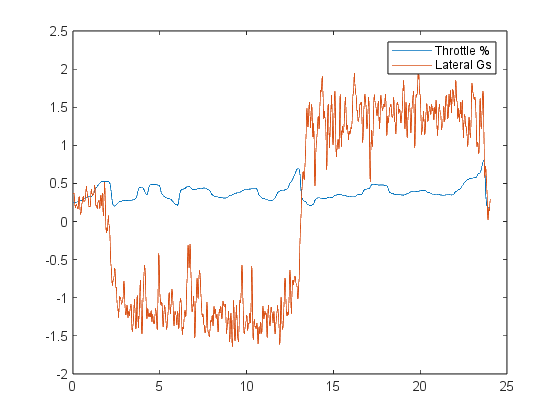

clf;

figure
plot(time,run.ThrottlePos ./ 100, time,gLat)
legend("Throttle %", "Lateral Gs")
title("")

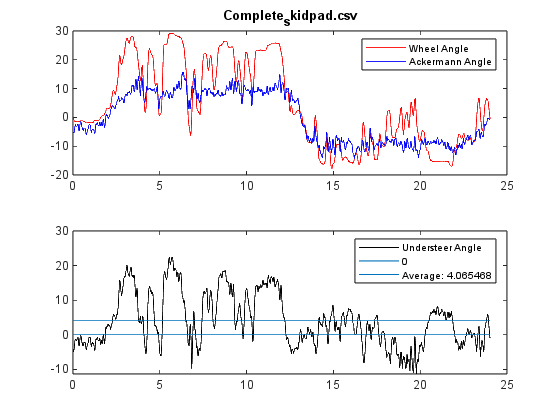


figure
UndersteerDisplay(filename, time, WA, AA, UA);

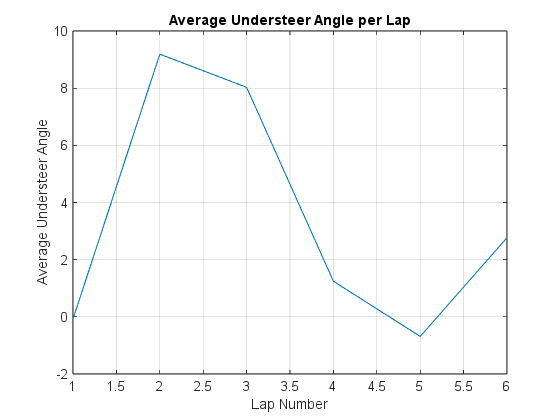


figure
plot(Lap, avgUA); grid on; title('Average Understeer Angle per Lap'); 
xlabel('Lap Number'); ylabel('Average Understeer Angle')

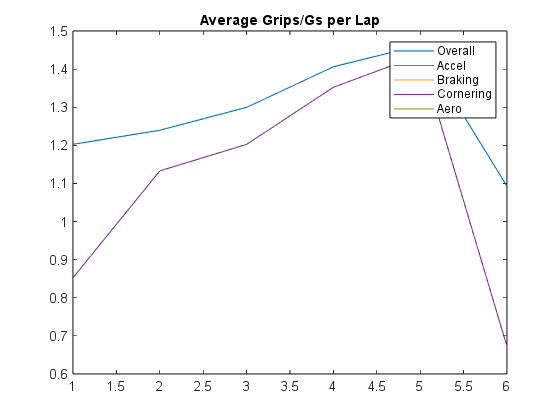


figure
plot(Lap, avgGO, ...
    Lap, avgGA, ...
    Lap, avgGB, ...
    Lap, avgGC, ...
    Lap, avgGAero)
title("Average Grips/Gs per Lap")
legend('Overall','Accel','Braking','Cornering','Aero')

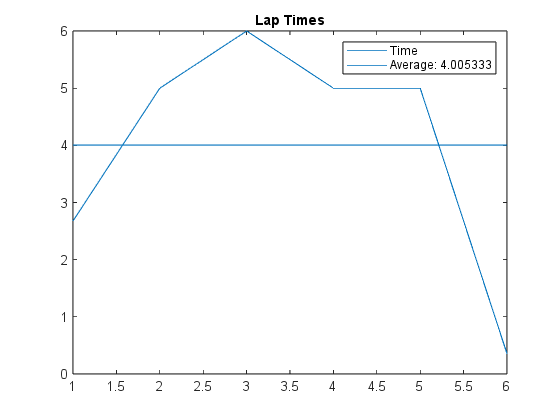


figure
plot(Lap,lapTimes)
title("Lap Times")
line([1 max(Lap)], [mean(lapTimes) mean(lapTimes)])
legend('Time', sprintf('Average: %f', mean(lapTimes)))

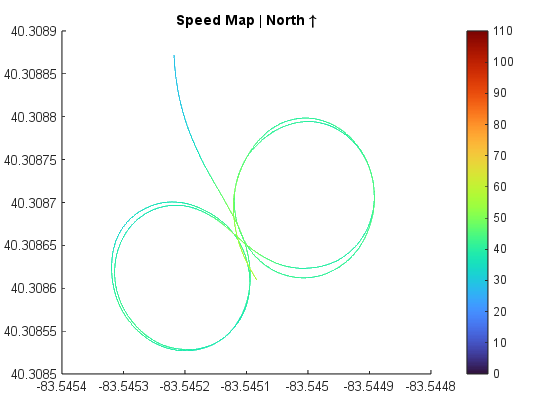


figure 
TrackDisplay(run.GPSLongitude, run.GPSLatitude, speed)
title("Speed Map | North \uparrow")

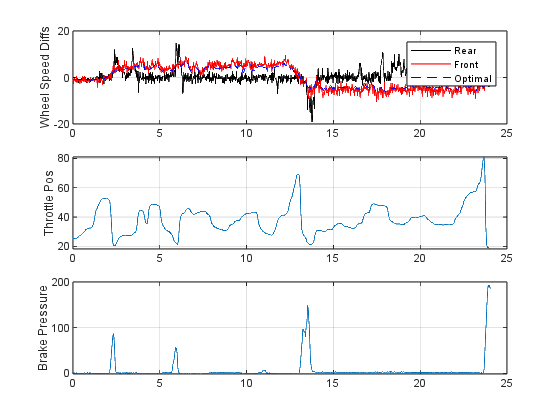


figure
title("Wheel Speed Differences")
WheelSpeedDiffDisplay(DiffF, DiffR, DiffO, run, time)

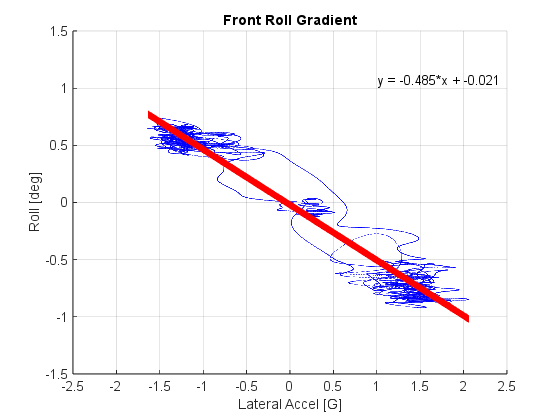

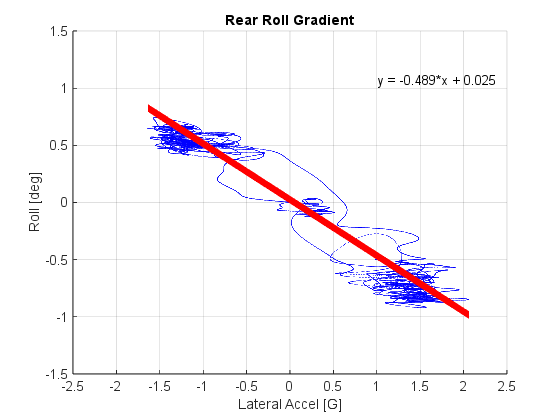

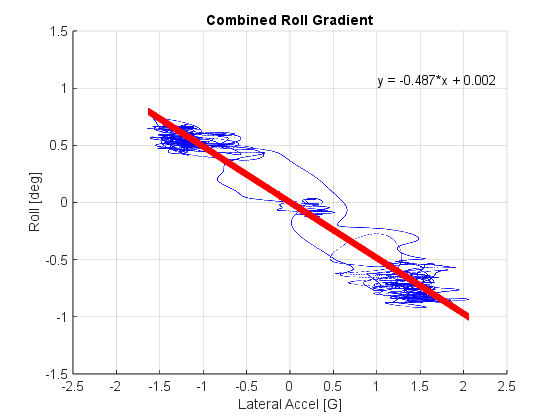

% RollGradient currently zeros the suspension position by itself
% and will not center properly with trimmed data
[RG_F,RG_R,RG] = RollGradient(run,1);

RollStiffnesses = RollStiffness(run,car) % Stiffness in kg mm/deg

RollStiffnesses = 7×2 table
        RollStiffnessComponents           Vals   
    _______________________________    __________

    "Total Roll Stiffness"             1.5774e+05
    "Front Roll Stiffness"                  79275
    "Rear Roll Stiffness"                   78466
    "Front Roll Stiffness - Spring"         46237
    "Rear Roll Stiffness - Spring"          50143
    "Front Roll Stiffness - ARB"            33038
    "Rear Roll Stiffness - ARB"             28322
